# **07 - Filtry s konečnou impulzní odezvou (FIR): část I.**

# **(návrh prototypem dolní propusti)**

Filtry představují lineární časově invariantní (LTI) systém, který přenáší/tlumí požadované frekvenční složky - **frekvenční pásmo**. Inverzním Fourierovým obrazem přenosové funkce filtru je jeho impulzní odezva, která je v případě FIR konečná (Finite Impulse Response). Signál je tedy průchodem systému konvolvován s konečnou impulzní odezvou - **konvoluční maskou**. Řád filtru ($M$) je odvozen od délky konvoluční masky (impulzní odezvy) ($M+1$). Matematicky řád filtru reprezentuje řád polynomu přenosové funkce $H\left\lbrack j\omega \right\rbrack$, která je frekvenčním obrazem $h\left\lbrack n\right\rbrack$. Diskrétní konvoluci lze rozepsat na diferenční rovnici, ze které také vyplývá mřížková struktura filtru (konvoluční automat). Signál postupně vstupuje do paměti systému, jejíž buňky jsou posunuty o jeden vzorek ($z^{-1}$). U FIR filtru je zavedeným pravidlem, že impulzní odezva $h\left\lbrack n\right\rbrack$ je značena jako $b\left\lbrack k\right\rbrack =h\left\lbrack n\right\rbrack$ a tvoří tak koeficienty filtru uvnitř mřížkové struktury. Pro intuitivnější značení budeme první vzorek signálu a impulzní odezvy uvažovat jako$n=0$, řád filtru $M$ pak odpovídá počtu zpožďovacích členů.   


$$y{\left[n\right]}=b_0 x{\left[n\right]}+b_1 x{\left[n-1\right]}+\ldots+b_M x{\left[n-M\right]}$$


Výstupem FIR filtru $y\left\lbrack n\right\rbrack$ je výsledek konvoluce impulzní odezvy $b\left\lbrack k\right\rbrack$ a vstupního signálu $x\left\lbrack n\right\rbrack$: $y\left\lbrack n\right\rbrack =b\left\lbrack k\right\rbrack *x\left\lbrack n\right\rbrack$, kde délka odezvy $K$ se nemusí rovnat délce signálu $N$; $K=M+1$*.*

Z věty o posunu v čase ve Fourierově transformaci vychází tzv. **Z-transformace** ($z^{-M} =\ e^{-i\omega M}$), tj. posun signálu v čase vede k fázovému posunu ve spektru. Z-transformace přepisuje diferenční rovnici (z časové oblasti) do komplexní z-roviny (frekvenční oblasti): $y\left\lbrack n-\Delta \right\rbrack \longrightarrow Y\left\lbrack z\right\rbrack \cdot z^{-\Delta }$, kde $\Delta \in \left\langle 0,M\right\rangle$. 

     
$$\begin{array}{l}
y{\left[n\right]}=b_0 x{\left[n\right]}+b_1 x{\left[n-1\right]}+\ldots+b_M x{\left[n-M\right]}\\
Y{\left[z\right]}=b_0 X{\left[z\right]}+b_1 X{\left[z\right]}z^{-1} +\ldots+b_M X{\left[z\right]}z^{-M} 
\end{array}$$


Řešení si lze představit jako superpozici spekter vstupního signálu $X{\left[z\right]}$, který je postupně pro každý zpožďovací člen fázově posunut o $z^{-k}$ a násoben koeficienty $b_k$. Sečtením/odečtením harmonických složek v protifázi/fázi tak dochází k potlačení/zesílení, tj. filtraci. 

Vyjádříme přenosovou funkci a dosadíme diferenciální rovnici po z-transformaci:

    
$$H\left\lbrack z\right\rbrack =\frac{Y\left\lbrack z\right\rbrack }{X\left\lbrack z\right\rbrack }$$


    
$$H\left\lbrack z\right\rbrack =\frac{b_0 X{\left[z\right]}+b_1 X{\left[z\right]}z^{-1} +\ldots+b_M X{\left[z\right]}z^{-M} }{X\left\lbrack z\right\rbrack }$$


Jmenovatel $X\left\lbrack z\right\rbrack$ se vykrátí ve jmenovateli za vzniku polynomu:

     
$$\begin{array}{l}
H{\left[z\right]}=b_0 +b_1 z^{-1} +\ldots+b_M z^{-M} \;\;\textrm{po}\;\textrm{úpravě}\;\textrm{vynásobením}\cdot \frac{z^M }{z^M }\\
H\left\lbrack z\right\rbrack =\frac{b_0 z^M +b_1 z^{M-1} +\ldotp \ldotp \ldotp +b_m }{z^M }
\end{array}$$


Vyřešením kořenů polynomu získáváme tzv. póly a nuly, ve kterých hodnoty z-roviny nabývají extrémních hodnot (nuly: 0, póly: $\infty$). U FIR jsou všechny póly $M$-násobné v 0.  Inverzní z-transformací (substitucí $z^{-M} =\ e^{i\omega M}$) vzniká komplexní z-rovina celého oboru komplexních čísel, které po dosazení do polynomu přenosové funkce vytvoří tzv. membránový model z-roviny. Membrána z-roviny je deformována pozicí nul a pólů. Přenos filtru je pak popsán hodnotami ležícími právě na jednotkové kružnici $\left|H\left\lbrack 1e^{j\omega } \right\rbrack \right|$.

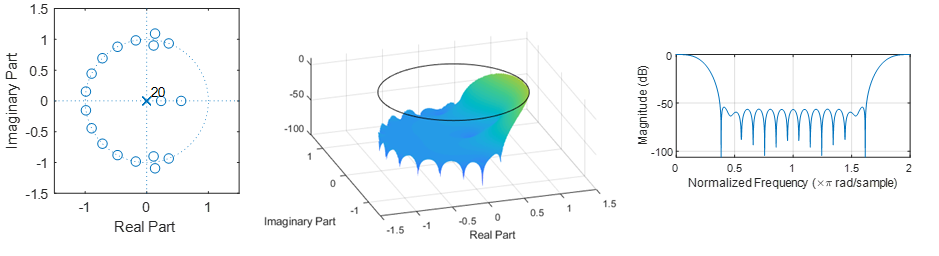

Uživatelský návrh filtru hledá polynom s koeficienty ${\mathrm{b}}_k$ (nuly a póly), aby přenosová funkce filtru splňovala požadavky na zlomový kmitočet $f_0$ (-3dB), přenos v propustném pásmu (~0 dB) a útlum v zádržném pásmu (např. < -60 dB). Nejjednodušším způsobem návrhu je využití prototypových funkcí, jejichž přenosová funkce je snadno popsatelná i v z-rovině. Touto funkcí je například tzv. sampling function:

    
$$\mathrm{s}\mathrm{i}\mathrm{n}\mathrm{c}{\left(\Omega_0 t\right)}=\frac{\mathrm{s}\mathrm{i}\mathrm{n}\left(\Omega_0 t\right)}{\Omega_0 t};t\in {\left(-\infty ,\infty \right)};\ \lim_{t\to 0} \mathrm{s}\mathrm{i}\mathrm{n}\mathrm{c}{\left(t\right)}=1$$


Jedná se o ideální dolní propust se zlomovým kmitočtem $f_0 =\frac{\Omega_0 }{2\pi }$ , ale jen v případě infinitní odezvy $t\in \left(-\infty ;\infty \right)$. 

V digitálním zpracivání signálů je ovšem výhodnější pracovat se vzorky $\left\lbrack n\right\rbrack$ a mezní kmitočat filtru (zlomový kmitočet) $f_0$ definovat poměrově k $f_s$. Přenosová funkce je proto uváděna pro normovaný kmitočet $\omega \in \left\langle 0,2\right\rangle$, který koresponduje s $f\in \left\langle 0,f_s \right\rangle$. Prostou trojčlenkou můžeme převádět frekvenci na normovaný kmitočet a zpět $\omega_0 =\frac{2f_0 }{fs}$ a realizaci provádět přímo ve vzorcích $\mathrm{s}\mathrm{i}\mathrm{n}\mathrm{c}{\left({\pi \omega }_0 n\right)}$. 

    
$$\mathrm{s}\mathrm{i}\mathrm{n}\mathrm{c}{\left({\pi \omega }_0 n\right)}=\frac{\mathrm{s}\mathrm{i}\mathrm{n}\left({\pi \omega }_0 n\right)}{{\pi \omega }_0 n};\ \lim_{n\to 0} \mathrm{s}\mathrm{i}\mathrm{n}\mathrm{c}{\left(n\right)}=1$$


Realizace impulzní odezvy pomocí $\textrm{sinc}\left(\;\right)$ funkce musí být na konečném časovém intervalu diskrétního času, tj. konečné délky $M+1$ a pro symetrický tvar s nulovou hodnotu času uprostře intervalu. 

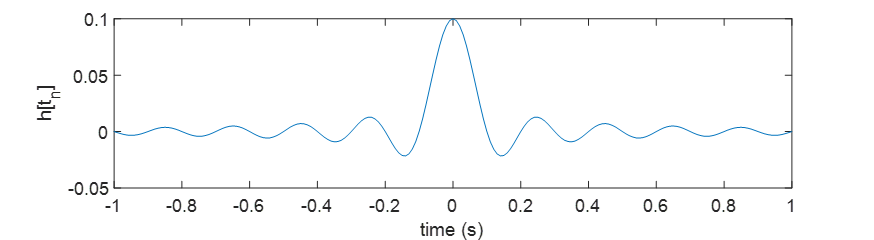

     $t_k \in \left\langle -\frac{\frac{M}{f_s }}{2};\;\frac{\frac{M}{f_s }}{2}\right\rangle$... diskrétní čas

     $n\in \left\langle -\frac{M}{2};\frac{M}{2}\right\rangle$ ... vzorky

Kratší impulzní odezva oproti  $n\in \left(-\infty ,\infty \right)$ se přenosová funkce vzdaluje od ideálu a dochází ke zvlnění a menší strmosti. Volba řádu filtru $M$ je tedy klíčovým parametrem ke splnění požadované strmosti a útlumu filtru. Zvlnění filtru lze omezit převážením $\textrm{sinc}\left(\;\right)$ funkce např. Hammingovým oknem $w\left\lbrack n\right\rbrack$: $\acute{b} \left\lbrack n\right\rbrack =b\left\lbrack n\right\rbrack \times w\left\lbrack n\right\rbrack$. 

Pokud je splněna symetrie/antisymetrie impulzní odezvy, má filtr lineární fázový přenos a **zpoždění filtru lze kompenzovat posunem výstupního signálu** zpět o $\frac{M}{2}$ vzorků $\acute{y} \left\lbrack n\right\rbrack =y\left\lbrack n+\frac{M}{2}\right\rbrack$.

Návrh horní, pásmové propusti a zádrže lze realizovat kombinací filtrů, distributivní zákon v LTI: $x{\left[n\right]}*\left(g{\left[k\right]}\pm h{\left[k\right]}\right)=X\left\lbrack f\right\rbrack \textrm{∙}{\left(G\left\lbrack f\right\rbrack \pm H\left\lbrack f\right\rbrack \right)}$. Např. horní propust (HP) je rovna rovnoměrnému spektru (spektrum jednotkového impulzu $\delta \left\lbrack n\right\rbrack$) bez dolní propusti: $x{\left[n\right]}*\left(\delta {\left[n\right]}-sinc\left({\pi \omega }_0 n\right)\right)$. **Pro zachování symetrie musí být řád filtru **$M$** sudý, délka impulzní odezvy **$h\left\lbrack n\right\rbrack$**, respektive **$b\left\lbrack n\right\rbrack$** je lichá **$M+1$** a jednotkový impulz leží přesně uprostřed**.

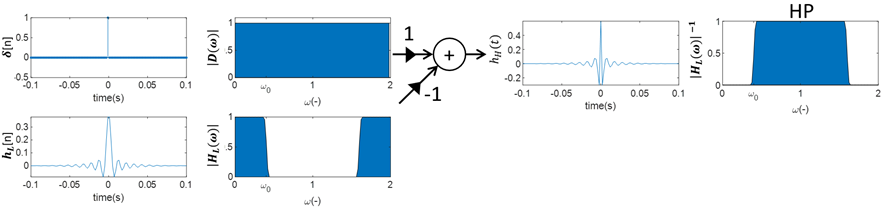

Kvalitu filtru nebo požadavky návrhu definujeme dle tolerančního pásma filtru, zde pro dolní propust:

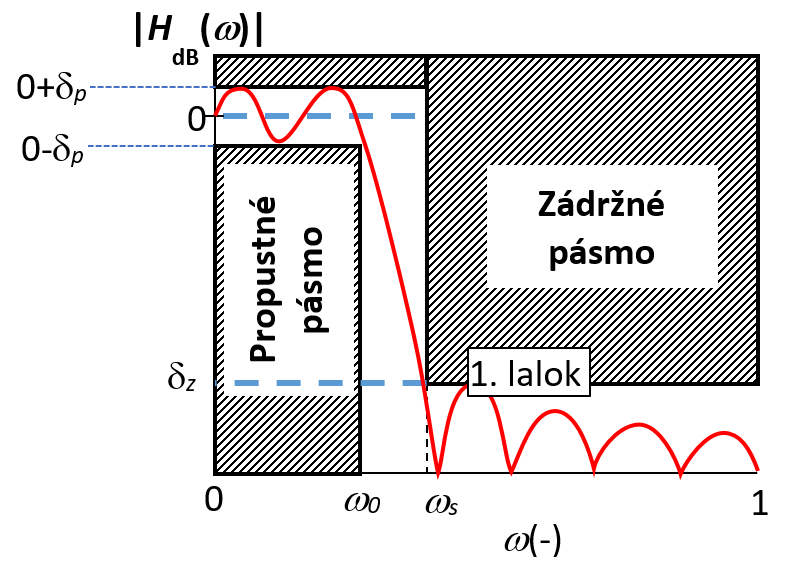

**Cíle:**

**Základní filtry:**

    **1) Návrh filtru prototypem sinc() funkce: **

- **Realizujte dolní propust DP:**

- **zobrazte impulzní odezvu**

- **zobrazte pozici nul a pólů v z-rovině**

- **zobrazte přenosovou funkci (amplitudovou i fázovou)**

- **sledujte vliv řádu filtru *****M***

- **Realizujte pásmová zádrž (PZ) jako kombinací dolní a horní propusti (DP a HP)**

**    2) Prakticý příklad: Filtrace EEG pro vizuální hodnocení**

- **Návrh pásmové propusti (PP)**

- **Filtrace signálu**

- **Kompenzace fázového zpoždění**

**Užitečné funkce: **`impz, zplane, freqz, pwelch, filter, fir1`

**Užitečné nástroje:**` filterDesigner`

## `Nápověda:`

### 1) Prototyp dolní propusti

Pomocí $\textrm{sinc}\left(\;\right)$ funkce navrhněte dolní propust. Podle teorie vytvořte impulzní odezvu filtru $h\left\lbrack t_n \right\rbrack$, kterou je nutno ještě normovat na jednotkovou plochu, čímž vznikne filtrační maska maska FIR filtru $b\left\lbrack n\right\rbrack =\frac{1}{A}h\left\lbrack n\right\rbrack$ dle normované funkce $h\left\lbrack n\right\rbrack =\textrm{sinc}\left(\pi \omega n\right)$:


$$\begin{array}{l}
h\left\lbrack t_n \right\rbrack =\textrm{sinc}\left(\Omega_0 t\right)=\frac{\sin \left(\Omega_0 t\right)}{\Omega_0 t};\;\;\;h\left\lbrack 0\right\rbrack =\textrm{sinc}\left(0\right)=1\\
A=\frac{f_s }{2f_0 }\;\\
n=\frac{t}{f_s }\\
\Omega_0 =2\pi f_0 =\pi \omega_0 \\
\omega_0 =\frac{2f_0 }{f_s };\;\omega_0 \in \left\langle 0,1\right\rangle \;\textrm{pokud}\;f_0 <\frac{f_s }{2}\;\ldotp \ldotp \ldotp \textrm{normovaný}\;\textrm{kmitočet}
\end{array}$$


_______________________________________________


$$\begin{array}{l}
h\left\lbrack n\right\rbrack =\textrm{sinc}\left(\pi \omega_0 n\right)=\frac{\sin \left(\pi \omega_0 n\right)}{\pi \omega_0 n};\;\;\;h\left\lbrack 0\right\rbrack =\textrm{sinc}\left(0\right)=1\\
b\left\lbrack n\right\rbrack =\frac{1}{A}h\left\lbrack n\right\rbrack 
\end{array}$$


Pokud délka **konečné impulzní odezvy** $h\left\lbrack t_n \right\rbrack$ je $T_n$, musí být definiční obor funkce $t_n \in \left\langle -\frac{T_n }{2};\;\frac{T_n }{2}\right\rangle$. To samé můžeme zapsat ve vzorcích; celková délka finitní impulzní odezvy $h\left\lbrack n\right\rbrack$ odpovídá $M+1$ vzorků, kde $M$ je řád filtru. Tedy pro diskrétní zápis $n\in \left\langle -\frac{M}{2};\frac{M}{2}\right\rangle$. Jelikož plocha pod křivkou $\sum_n h\left\lbrack n\right\rbrack >1$, docházelo by po filtraci k zesílení. Finální impulzní odezva DP (koeficienty filtru) $b\left\lbrack n\right\rbrack =\frac{1}{A}h\left\lbrack n\right\rbrack$. Koeficient $A$ normalizuje plochu pod křivkou (intenzitu) na jednotkovou. 

**Navrhněte impulzní odezvu dolní propusti (DP), která pro **`fs=1000`** Hz bude mít mezní kmitočet **`f0=250`** Hz a řád filtru **`M=10:`

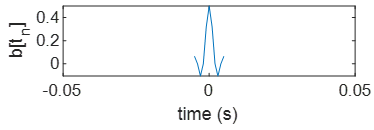

fs=1000; % Hz vzorkovací kmitočet
f0=250; % Hz mezní kmitočet filtru
M=10; % řád filtru
n = -M/2:M/2;        % n=... v intervalu <-M/2; M/2>
w0 = 2*f0/fs ;       % w0=... normovaný mezní kmitočet filtru
        
h = sin(pi*w0*n)./(pi*w0*n);        % h=... h[n] dle předpisu sinc() funkce
h(M/2+1) = 1;       % h[0]=1... pro čas t=0 je hodnota sinc(0)=1
A = fs/(2*f0);        % A=... koeficient normalizující sum(h[n])=1;
b = 1/A*h;        % b=... impulzní odezva filtru 

t_n = n/fs;        % t_n=... pro vykreslení v čase přepočítejte vektor "n" na čas t_n


Spočtěte přenosovou funkci filtru$H\left\lbrack f_k \right\rbrack$, zobrazte absolutní přenos (magnitudové spektrum) a fázové zpoždění (fázové spektrum). Využijte Fourierovy transformace, nebo rovnou funkce `freqz()`. Zobrazte rozložení pólů (x) a nul (o) přenosové funkce v z-rovině (membránový model) - funkce `zplane()`.

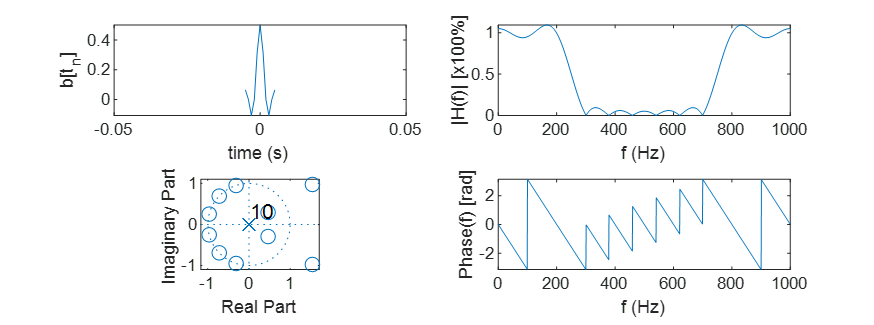a v dB: 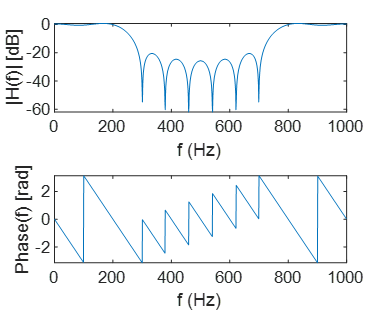

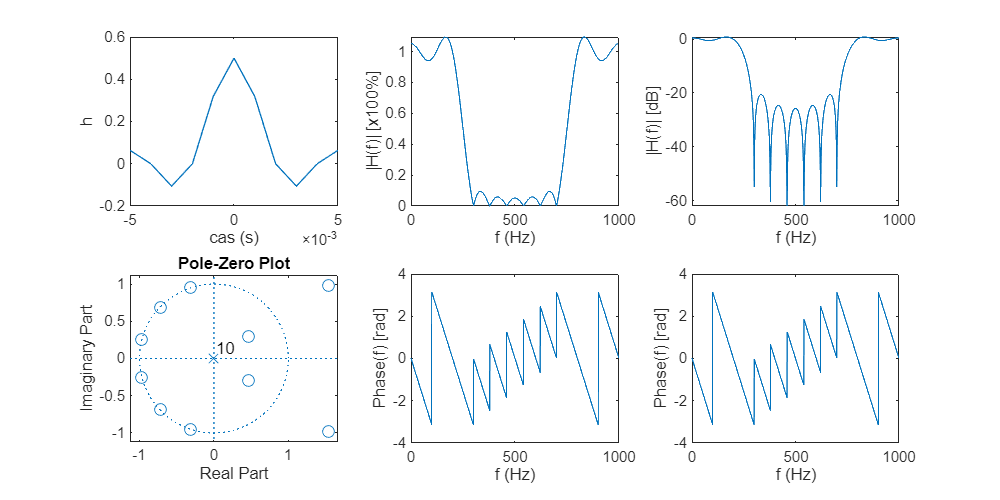

H = fft(b,fs);
f = linspace(0,fs-1,length(H));
figure
set(gcf,'Position', [0 0 800 400])
subplot(231)
plot(t_n,b)
xlabel('cas (s)')
ylabel('h')

subplot(232)
plot(f, abs(H))
xlabel('f (Hz)')
ylabel("|H(f)| [x100%]")
subplot(233)
plot(f, 20*log10(abs(H)))
xlabel('f (Hz)')
ylabel("|H(f)| [dB]")
subplot(234)
zplane(b,1)

subplot(235)
plot(f,angle(H))
xlabel('f (Hz)')
ylabel('Phase(f) [rad]')
subplot(236)
plot(f,angle(H))
xlabel('f (Hz)')
ylabel('Phase(f) [rad]')

H_dB = 20*log10(abs(H));
max_zvlneni = max(H_dB)

max_zvlneni = 0.7817

f0 = f(H_dB(1:fs/2) == min(H_dB(H_dB>-3)))

f0 = 232

H_dB(f == 333)

ans = -20.5217

Dobře si všimněte, že přenos v propustném pásmu je zvlněný, ačkoli bychom od filtru očekávali, že v propustném pásmu nebude frekvenční složky měnit a přenos $H\left\lbrack f\right\rbrack =1\;\left(0\;\textrm{dB}\right);\;f<f_0$. Mezní kmitočet $f_0$ je definován pro místo, kde přenos klesne na $\frac{1}{\sqrt{2}}=0\ldotp 7071$ (-3 dB), jinými slovy útlum vzroste o 3 dB. 

$|H\left\lbrack f_0 \right\rbrack |=-3\;\textrm{dB}$. 

Pozn.: výpočet dB pro přenos je poměr vstupní a výstupní skalární veličiny, tedy $H_{\textrm{dB}} =20\cdot \log_{10} \left(H\right)$.

**Odečtěte reálné hodnoty z grafu a odpovězte:**

**Maximální zvlnění** **v propustném pásmu **$\delta_p$ **filtru je 0.7817 dB**

**Mezní kmitočet **$f_0$ **navrženého filtru, kde přenos je -3 dB, je 232 Hz.**

**Útlum  v zádržném pásmu na prvním laloku (333 Hz) je -20.52 dB.**

Modifikujte tvar impulzní odezvy $b\left\lbrack n\right\rbrack$ filtru jeho přenásobením Hammingovým oknem $w\left\lbrack n\right\rbrack$, čímž dojde k potlačení okrajů impulzní odezvy, vyhlazení přenosové funkce a mírním snížením strmosti filtru:

w = hamming(length(h));
bw = b.*w'% bw[n]=b[n] x w[n] skalární násobení (.*), pozor na orientaci vektorů (');

bw =     0.0051   -0.0000   -0.0422    0.0000    0.2903    0.5000    0.2903    0.0000   -0.0422   -0.0000    0.0051


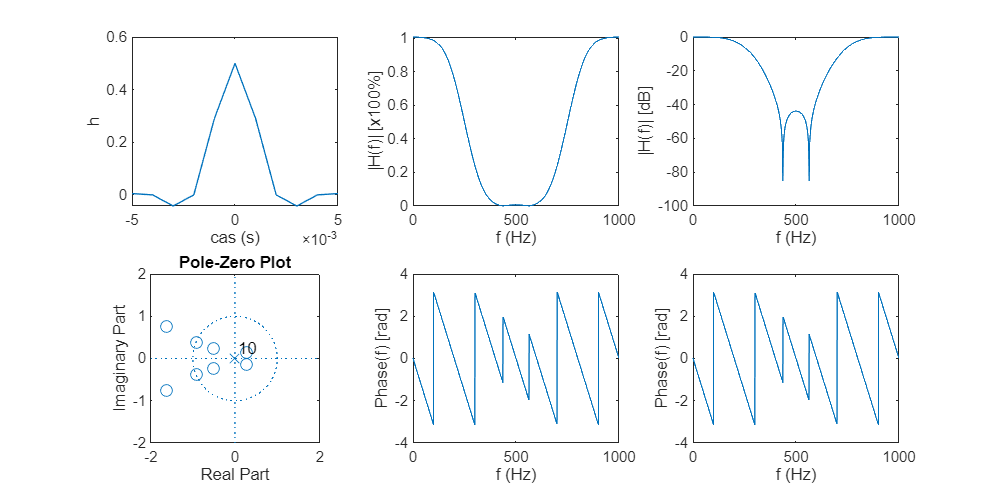

[H, H_dB] = fir_plot(bw,fs,t_n);

max_zvlneni = max(H_dB)

max_zvlneni = 0.0558

f0 = f(H_dB(1:fs/2) == min(H_dB(H_dB>-3)))

f0 = 210

H_dB(f == 333)

ans = -18.3373

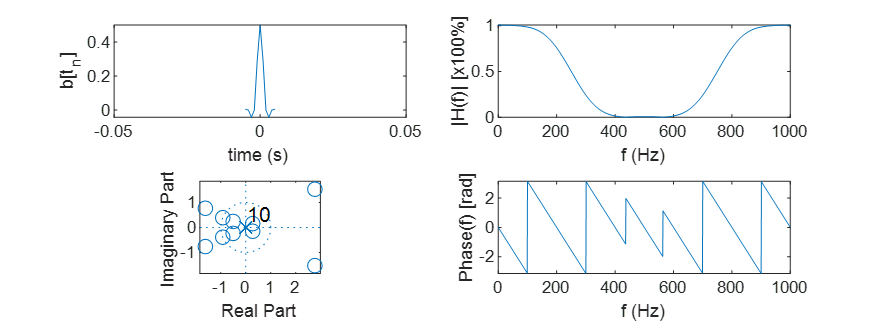a v dB: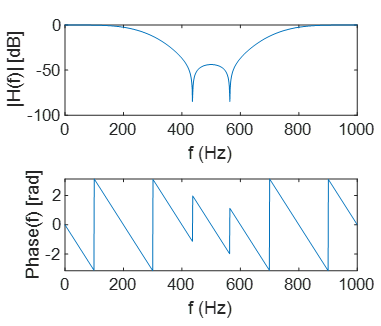

Znovu odpovězte na otázky a doplňte, zdali se jedná o zlepšení či zhoršení:

**Maximální zvlnění v propustném pásmu **$\delta_p$** filtru je 0.0558 dB, jedná se o **lepší** parametr než bez převážení oknem.**

**Mezní kmitočet **$f_0$ **navrženého filtru, kde přenos je -3 dB, je 210 Hz, , jedná se o **horší** parametr než bez převážení oknem.**

**Útlum v zádržném pásmu na frekvenci 333 Hz je -18.33 dB, jedná se o **horší** parametr než bez převážení oknem.**

**Navrhněte obdobnou dolní propust pro stejný mezní kmitočet **$f_0 =250\;\textrm{Hz}$** pro **$f_s =1000\;\textrm{Hz}$**, ale výrazně vyšího řádu **$M=100$**.** 

Využijte návrhu s převážením Hammingovým oknem a porovnejte parametry filtru pro řád $M=10$ oproti $M=100$.

 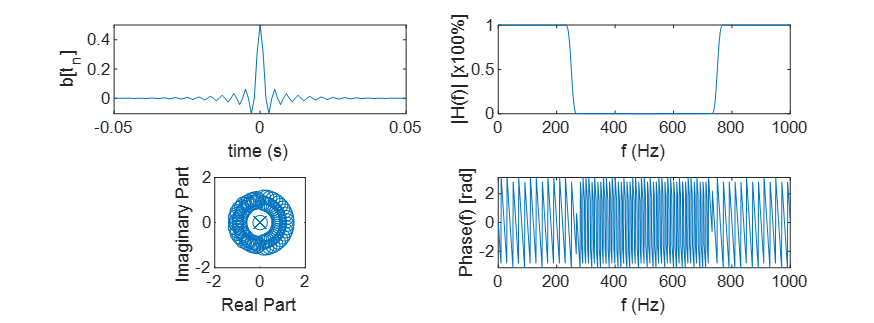a v dB: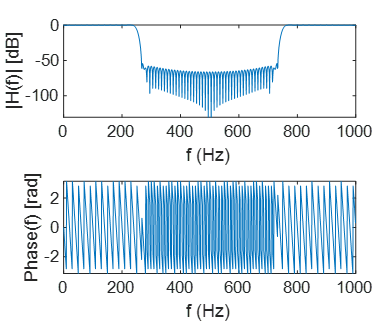

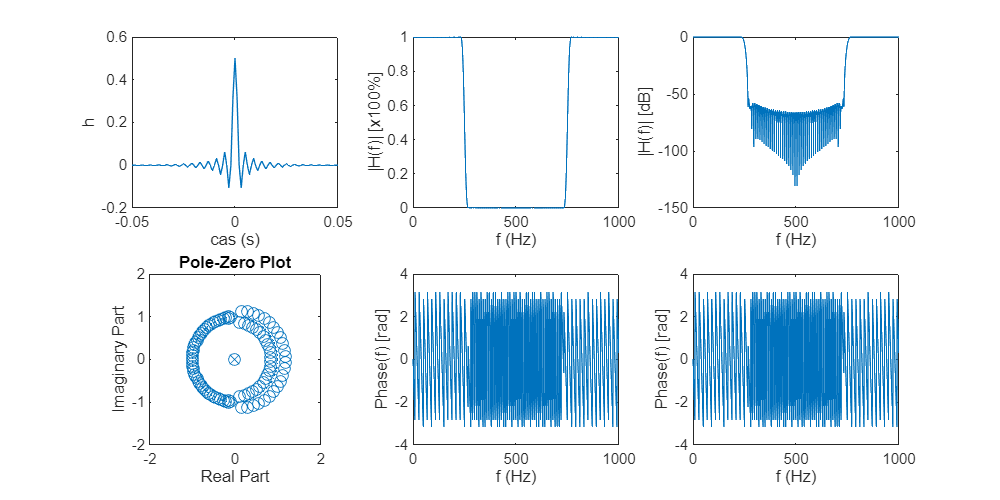


fs=1000; % Hz vzorkovací kmitočet
f0=250; % Hz mezní kmitočet filtru
M=100; % řád filtru
n = -M/2:M/2;        % n=... v intervalu <-M/2; M/2>
w0 = 2*f0/fs ;       % w0=... normovaný mezní kmitočet filtru
        
h = sin(pi*w0*n)./(pi*w0*n);        % h=... h[n] dle předpisu sinc() funkce
h(M/2+1) = 1;       % h[0]=1... pro čas t=0 je hodnota sinc(0)=1
A = fs/(2*f0);        % A=... koeficient normalizující sum(h[n])=1;
b = 1/A*h;        % b=... impulzní odezva filtru 
bw = b.*hamming(length(h))';
t_n = n/fs;

[H, H_dB] = fir_plot(bw,fs,t_n);

f0 = f(H_dB(1:fs/2) == min(H_dB(H_dB>-3)))

f0 = 245

H_dB(f == 333)

ans = -64.8489

**Porovnejte filtry:**

        $M$**        |        **$f_0$**        |        **$|H\left(333\;\textrm{Hz}\right)|$

**        10        |       210         |             -18.33**

**        100      |      245         |             -64.84**

### **Pomocí dolních propustí navrhněte pásmovou zádrž (PZ).**

clear all

Z teorie o LTI systémem již víte, že platí princip superpozice, tj. stejně jako v časové oblasti pro impulzní odezvy, tak i ve frekvenční pro jejich přenosové funkce: $h\left\lbrack n\right\rbrack +g\left\lbrack n\right\rbrack =H\left\lbrack f\right\rbrack +G\left\lbrack f\right\rbrack$.

Pásmovou zádrž lze tedy realizovat jako kombinaci dolní propusti (DP) s mezním kmitočtem $f_{0_{\textrm{low}} }$ a horní propusti (HP) s mezním kmitočtem $f_{0_{\textrm{high}} }$:


$$h_{\textrm{DP}} \left\lbrack n\right\rbrack +h_{\textrm{HP}} \left\lbrack n\right\rbrack \approx H_{\textrm{DP}} \left\lbrack f\right\rbrack +H_{\textrm{HP}} \left\lbrack f\right\rbrack$$


Přenosová charakteristika horní propusti $1-H\left\lbrack f\right\rbrack$ je tedy inverzní k dolní propusti $H\left\lbrack f\right\rbrack$.  Lze opět využít principu superpozice, kdy ze znalosti konstantního přenosu $D\left\lbrack f\right\rbrack =1$ jednotkového impulzu $\delta \left\lbrack n\right\rbrack$ můžeme realizovat impulzní odezvu horní propusti jako jednotkový impulz minus impulzní odezva dolní propusti: $\delta \left\lbrack n\right\rbrack -h\left\lbrack n\right\rbrack$.

Pro realizaci pásmové zádrže s mezními kmitočty $f_{0_{\textrm{low}} }$ a $f_{0_{\textrm{high}} }$ tedy budeme potřebovat realizovat dvě dolní propusti s impulzními odezvami $h_{\textrm{low}} \left\lbrack n\right\rbrack$ a $h_{\textrm{high}} \left\lbrack n\right\rbrack$, přičemž druhou využijeme pro realizaci horní propusti $g\left\lbrack n\right\rbrack =\delta \left\lbrack n\right\rbrack -h_{\textrm{high}} \left\lbrack n\right\rbrack$. Impulzní odezva je tedy dána:


$$h\left\lbrack n\right\rbrack =h_{\textrm{low}} \left\lbrack n\right\rbrack +\left(\delta \left\lbrack n\right\rbrack -h_{\textrm{high}} \left\lbrack n\right\rbrack \right);\;\;\;\delta \left\lbrack 0\right\rbrack =1$$
   

Pro realizaci filtru ovšem opět musíme kompenzovat plochu pod impulzní odezvou na jednotkovou. Proto při návrhu jednotlivých dolních propustí musíme provést normalizaci amplitudy:


$$\begin{array}{l}
b\left\lbrack n\right\rbrack =\frac{1}{A}h_{\textrm{low}} \left\lbrack n\right\rbrack +\left(\delta \left\lbrack n\right\rbrack -\frac{1}{B}h_{\textrm{high}} \left\lbrack n\right\rbrack \right)\\
A=\frac{f_s }{2f_{0_{\textrm{low}} } }\;\;\;\mathrm{a}\;\;\;\;B=\frac{f_s }{2f_{0_{\textrm{high}} } }
\end{array}$$


Celý vzorec lze tedy rozepsat pomocí součtu $\textrm{sinc}\left(\;\right)$ funkcí:


$$b\left\lbrack n\right\rbrack =\frac{1}{A}\textrm{sinc}\left(\pi \omega_{0_{\textrm{low}} } n\right)+\left(\delta \left\lbrack n\right\rbrack -\frac{1}{B}\textrm{sinc}\left(\pi {\omega_0 }_{\textrm{high}} n\right)\right)$$


Jen připomínáme, že $\textrm{sinc}\left(0\right)=1$ a $\delta \left\lbrack 0\right\rbrack =1$. Impulzní odezva musí být symetrická kolem $t=0$, tedy řád filtru $M$ musí být sudý, tj. délka impulzní odezvy lichá $M+1$. Na závěr upravte impulzní odezvu filtru Hammingovým oknem.


$$\acute{b} \left\lbrack n\right\rbrack =b\left\lbrack n\right\rbrack w\left\lbrack n\right\rbrack$$


**Realizujte pásmovou zádrž (PZ) řádu **$M=100$ **pro **$f_s =1000\;\textrm{Hz}$**, která bude tlumit frekvence v rozsahu 150 až 350 Hz (**$f_{0_{\textrm{low}} } =150\;\textrm{Hz},f_{0_{\textrm{high}} } =350\;\textrm{Hz}$**). **

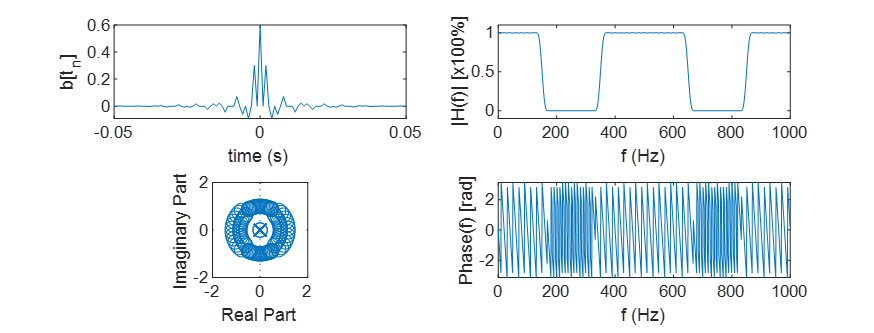a v dB: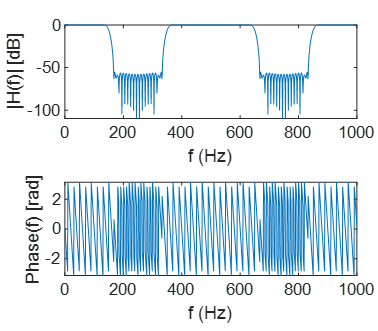 

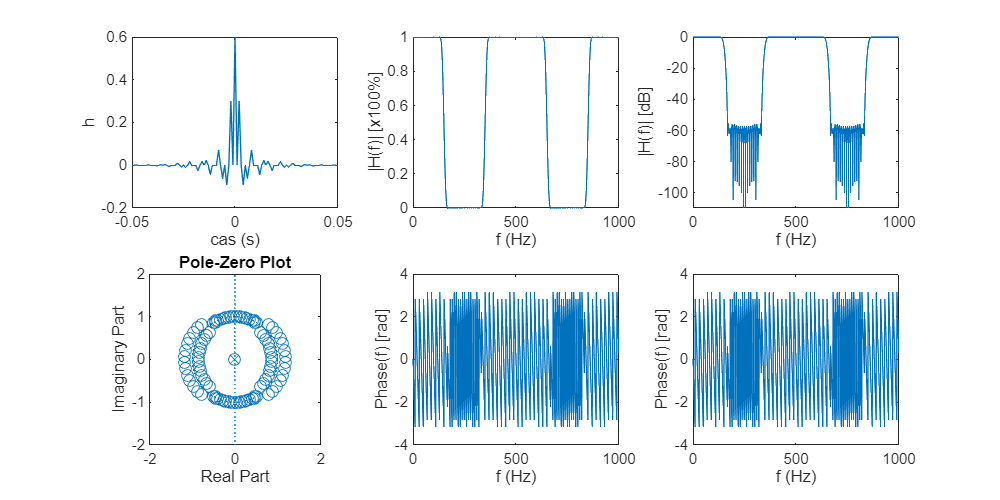

M = 100;

fs = 1000;
f_low = 150;
f_high = 350;
n = -M/2:M/2;
A = fs/(2*f_low);
B = fs/(2*f_high);
w_low = (2*f_low)/fs;
w_high = (2*f_high)/fs;
dirac = zeros([(M+1) 1]);
dirac(M/2+1) = 1;
b_low = sinc(w_low.*n);
b_low(M/2+1) = 1;
b_low = b_low/A;
b_high = sinc(w_high*n);
b_high(M/2+1) = 1;
b_high = b_high/B;
b = b_low + (dirac' - b_high);
bw = b.*hamming(length(b))';
t_n = n/fs;
fir_plot(bw,fs,t_n);


## **2) Filtrace iEEG v pásmu 0.5 až 45 Hz**

V klinické praxi se pro zběžné prohlížení signálů používají jednoduché filtry, jež odstraňují běžné artefakty v signálu.

Kolísání izolinie signálu

Vlivem elektrolitického spojení kovové snímací elektrody a kůže dochází k přenosu náboje elektrochemicky, pomocí iontů v použitém vodivém gelu, potu či tělními tekutinami. Přechod* kov - elektrolit - tkáň/kůže* si lze přectavit jako RLC článek. Vlivem pohybu (změna kapacity C) a změnou koncentrace elektrolitu např. vysycháním (změna R), pohybem vodičů v magnetickém poly (indukce na L) začne izolinie signálu kolísat, slangově "signál plave" orpoti referenci. Tato změna je relativně pomalá a děje se typicky pod frekvencí **0.5 Hz**.   

Síťové rušení 50 Hz

Všudypřítomné síťové rušení se indukuje na snímací elektrody (přes plochu smyčky) a ruší signál. Již umíte filtrovat násobky 50 Hz ve spektru, zde si úkol zjednodušíme. Navrhneme filtr, který spektrum **ořízne nad 45 Hz**.

Navrhněte pomocí prototypových oken **pásmovou propust (PP) v pásmu 0.5 - 45 Hz**. Zvolte řád filtru např. $M=1000$, nebo dle uvážení.

Nápověda: navrhněte dplní propust $b_{\textrm{high}}$s mezním kmitočtem $f_{\textrm{high}} =45\;\textrm{Hz}$. Navrhněte dolní propust $b_{\textrm{low}}$ s mezním kmitočtem $f_{\textrm{low}} =0\ldotp 5\;\textrm{Hz}$. Kombinací navrhněte impulzní odezvu filtru pásmové propusti $b_{\textrm{pp}} =b_{\textrm{high}} -b_{\textrm{low}}$. Nezapomeňte při návrhu kompenzovat zesílení propustí a finální impuzní odezvu převážit oknem. Pro ověření správnosti návrhu si zobrazte impulzní odezvu a přenosovou charakteristiku.

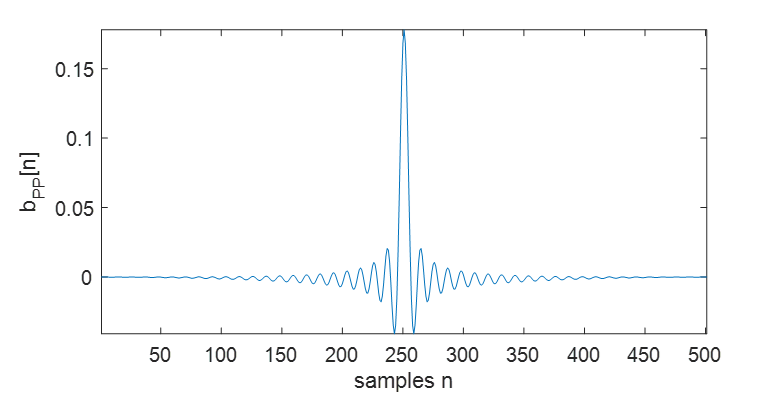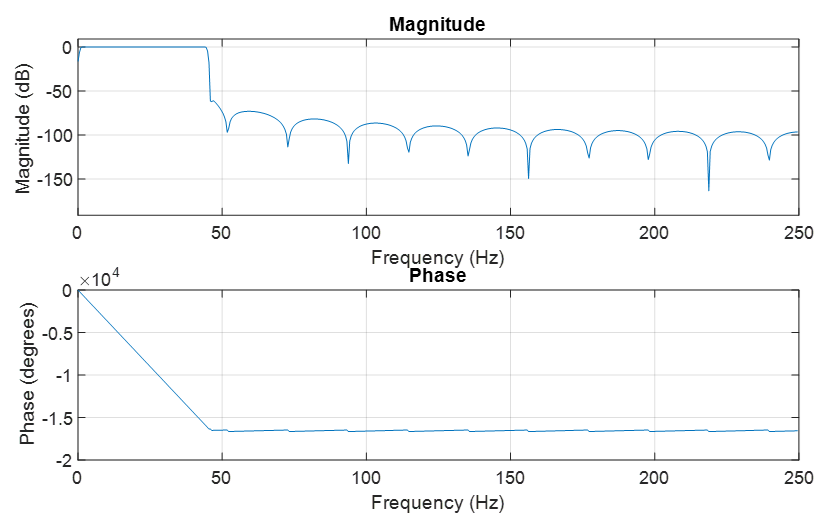

Pozn.: povšiměte si lineární fázové charakteristiky filtru (propustná část)

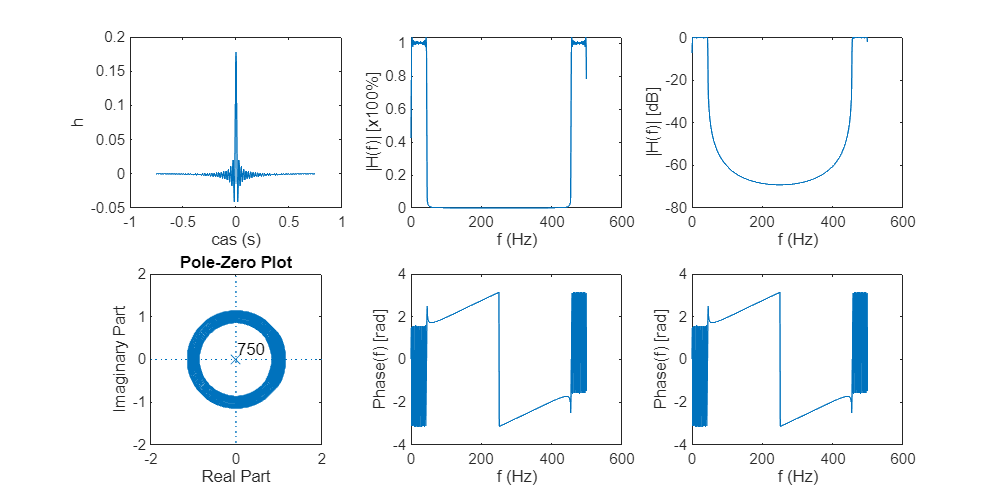

fs=500; % Hz vzorkovací kmitočet
f_high=45; % Hz mezní kmitočet filtru
M=750; % řád filtru
n = -M/2:M/2;       
w_high = 2*f_high/fs ;       
        
h_high = sin(pi*w_high*n)./(pi*w_high*n);        
h_high(M/2+1) = 1;       
A = fs/(2*f_high);        
b_high = 1/A*h_high;        

f_low = 0.5;

w_low = 2*f_low/fs ;               
h_low = sin(pi*w_low*n)./(pi*w_low*n);        
h_low(M/2+1) = 1;       
B = fs/(2*f_low);        
b_low = 1/B*h_low;
b = b_high - b_low;
bw = b.*hamming(length(b_low))';
t_n = n/fs;
[H, H_dB] = fir_plot(bw,fs,t_n);

disp(H(1))

    0.4257



**Jaký je útlum filtru pro stejnosměrnou složku v dB?**

$\left|H_{\mathrm{dB}} \left(0\right)\right|=$-6.12 dB

$\left|H\left(0\right)\right|=$0.494 poměrově

**Kolikrát se zmenší stejnosměná složka po filtraci? 0.494 krát**

Tip.: V praxi může stejnosměrná složka být natolik vysoká, že filtr není schopen ji odtranit.  Pro její odstraněnní si pomůžeme odečtením průměrné hodnoty od signálu před samotnou filtrací.

Načtěte a zobrazte signál `iEEG_izoline_50Hz.mat`. Hodnoty apmplitudy jsou v uV. 

Zobrazte absolutní spektrum nebo odhad spektra. Pozn.: správnou hodnotu výkonu neřešte, tj. nemusíte přepočítávat uV na V.

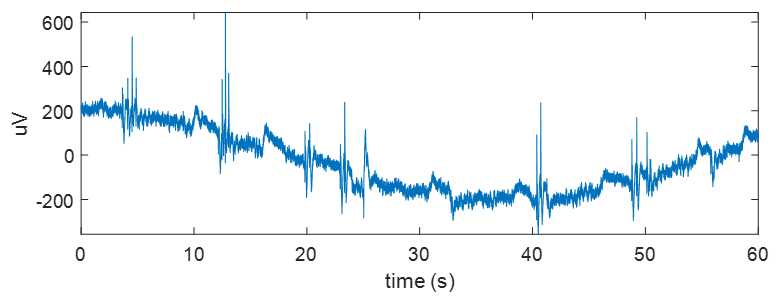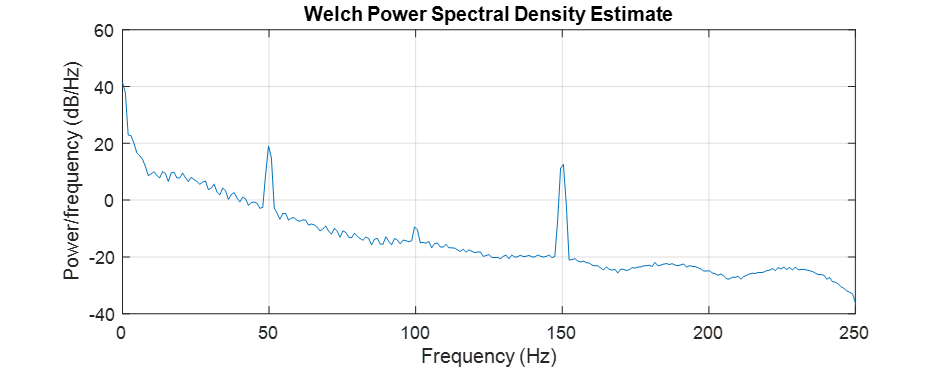

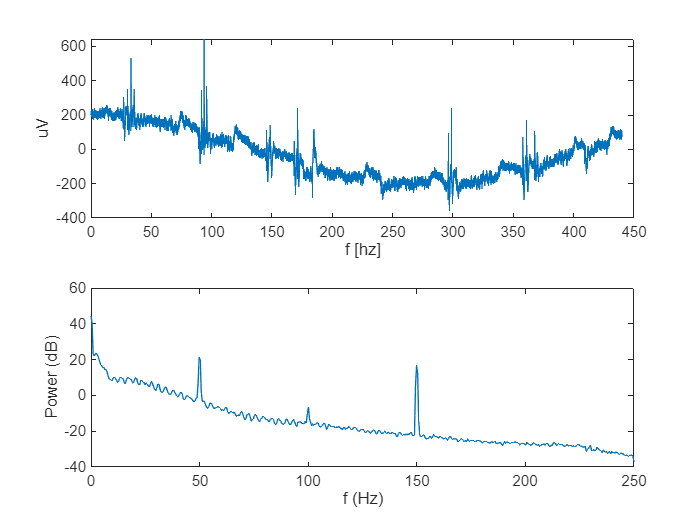

load("iEEG_izoline_50Hz.mat")
N = length(x);
F = linspace(0,fs-N/fs,N);
figure
subplot(211)
plot(F,x)
ylabel("uV")
xlabel("f [hz]")
subplot(212)
[psd,F_psd] = pwelch(x,1024,[],[],fs);
plot(F_psd,10*log10(psd));
xlabel("f (Hz)")
ylabel("Power (dB)")

Vyfiltrujte signál navrženou pásmovou propustí. Využijeme funkce `filter `(prozkoumejte dokumentaci), která relaizuje průchot signálu dle diferenční rovnice s koeficienty $b_{\textrm{PP}}$. Výpočet lze realizovat i prostou konvolucí, avšak museli bychom obtížně řešit okraje.

a=1; % koeficinty IIR filtru (detailněji v 9. přednášce). U FIR nastavujeme a=1;
x_filtered=filter(bw,a,x); % x...signál, b...koeficienty FIR filtru (impulzní odezva)

Zobrazte filtrovaný signál a jeho spektrum nebo odhad spetkra. Všiměte si, že došlo k vyrovnání izolinie a vyčištění signálu.

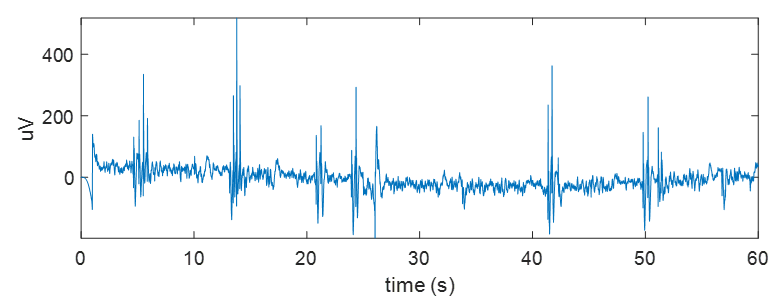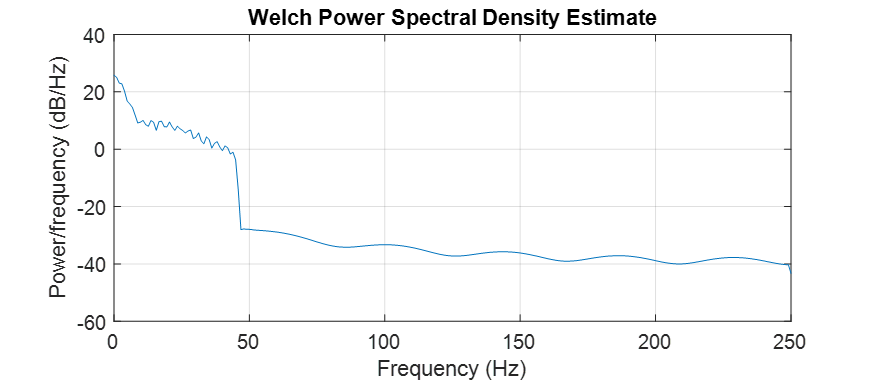

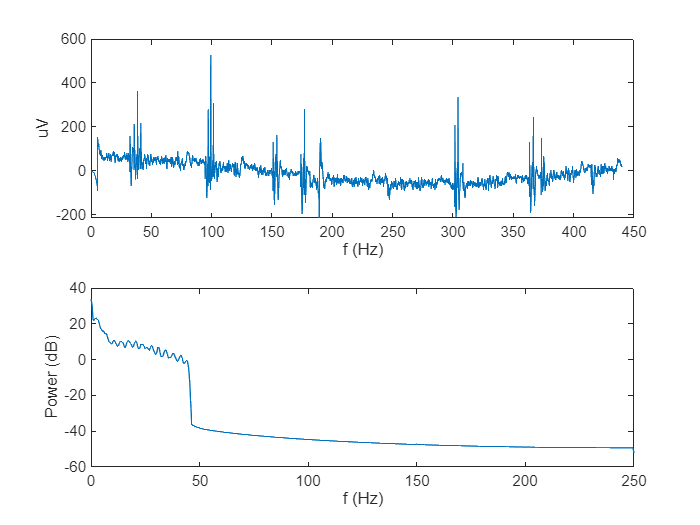

figure 
subplot(211)
plot(F,x_filtered)
xlabel("f (Hz)")
ylabel("uV")
[psd,F_psd] = pwelch(x_filtered,1024,[],[],fs);
subplot(212)
plot(F_psd,10*log10(psd));
ylabel("Power (dB)")
xlabel("f (Hz)")

V záznamu EEG se vyskytuje patologická epiletiformní aktivita, tzv. interiktální výboje. Vyberte si libovolný výboj a určete přesný čas jaho maxima v nefiltrovaném a filtrovaném signálu. Můžete také využít funkce `max()`, jehož druhým výstupem je pozice maxima ve vzorcích (index). Rozdíl orientačně odpovídá zpoždění filtru (šum v nefiltrovaném signálu může zkreslit maximum výboje).

[M1,I1]=max(x)

M1 = 643.0706

I1 = 6393

I1/fs

ans = 12.7860

[M2,I2]=max(x_filtered)

M2 = 527.7743

I2 = 6769

I2/fs

ans = 13.5380

DELAY=I2-I1

DELAY = 376

DELAY/fs

ans = 0.7520

**Zapište pozici vybraného výboje v původním nefiltrovaném signálu:**

**vzorek 6393  **

**v čase 12.78s**

**Pozici vybraného výboje ve filtrovaném signálu:**

**vzorek 6769    **

**v čase 13.53s**

**Spočtěte zpoždění filtru? **

**ve vzorcích 376**

**v sekundách 0.752s**

### **Kompenzace lineárního zpoždění filtru**

Měřené zpoždění by mělo přibližně odpovídat teoretickému předpokladu. Použitý FIR má symetrickou impulzní odezvu, jeho fáze je tedy lineární a zpoždění lze kompenzovat posunem filtrovaného signálu o polovinu řádu fitru $\frac{M}{2}$. 

Posun konpenzujeme oříznutím začátku, tj. odtraníme prvních $\frac{M}{2}$ vzorků. Uvědomme si, že dojde ke zkrácení signálu a tedy musíme vygenerovat novou časovou osu, nebo použít původní a oříznou posledních $\frac{M}{2}$ vzorků.

Zobrazte společně původní signál s filtrovaným časově kompnezvaným. 

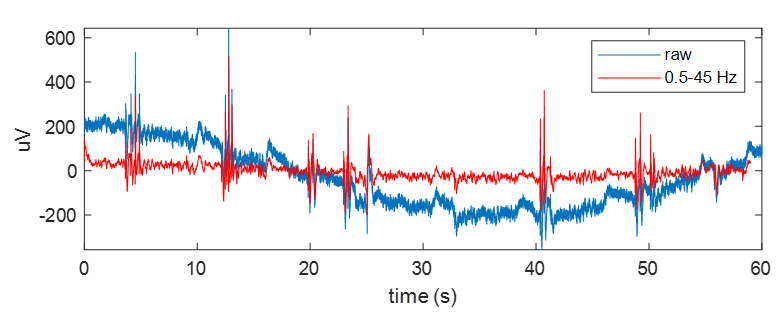

Detail: 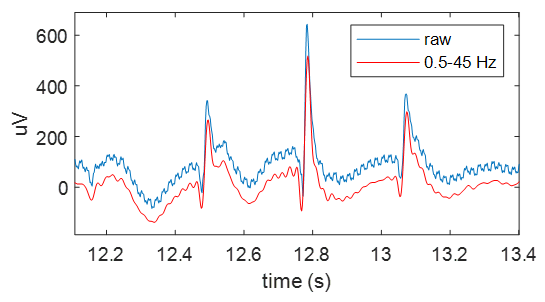

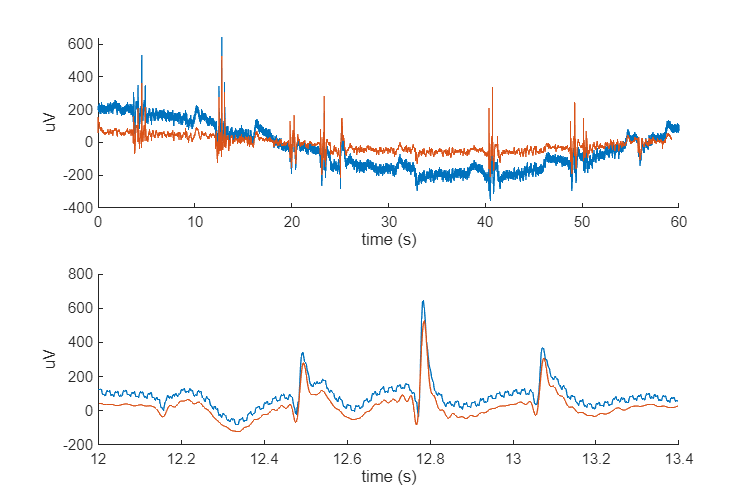

xf_crop = x_filtered;
xf_crop = xf_crop(M/2+1:end);
T = N/fs;
t = linspace(0,T - 1/fs,N);
t_crop = t(1:end-M/2);
figure
subplot(211);
set(gcf,'Position',[0 0 600 400])
hold on
plot(t,x)
plot(t_crop,xf_crop)
xlabel("time (s)")
ylabel("uV")
hold off
subplot(212)
hold on
idx = t>12 & t<13.4;
plot(t(idx),x(idx))
plot(t_crop(idx),xf_crop(idx))
xlabel("time (s)")
ylabel("uV")